# 1. Podzadatak

clear all

vrijednosti

a1=96;
a2=82;
a3=24;
px=173;
py=86;
fi=22

fi = 22


pwx=px-a3*cosd(fi)

pwx = 150.7476

pwy=py-a3*sind(fi)

pwy = 77.0094


s = sqrt(pwx^2 + pwy^2)

s = 169.2787

a1a2 = a1 + a2

a1a2 = 178

%rješenje je moguće

theta 2

cosTheta2=(pwx^2+pwy^2-a1^2-a2^2)/(2*a1*a2)

cosTheta2 = 0.8076

theta2a=acos(cosTheta2)*180/pi

theta2a = 36.1352

theta2b=-acos(cosTheta2)*180/pi

theta2b = -36.1352

alfa i beta

alfa=atan(pwy/pwx)*180/pi

alfa = 27.0602

beta=acos((pwx^2+pwy^2+a1^2-a2^2)/(2*a1*sqrt(pwx^2+pwy^2)))*180/pi

beta = 16.5978

zadana konfiguracija + (alfa + beta), theta 1

theta1a=alfa-beta

theta1a = 10.4624

theta1b=alfa+beta

theta1b = 43.6581


psxa=a1*cosd(theta1a)

psxa = 94.4039

psya=a1*sind(theta1a)

psya = 17.4327

psxb=a1*cosd(theta1b)

psxb = 69.4534

psyb=a1*sind(theta1b)

psyb = 66.2739

theta 3

theta3a=fi-theta1a-theta2a;
theta3b=fi-theta1b-theta2b;

## **Rješenje**

qa = [theta1a theta2a theta3a]

qa =    10.4624   36.1352  -24.5976


qb = [theta1b theta2b theta3b]

qb =    43.6581  -36.1352   14.4772


## **Crtež**

plot(0,0,'*'); hold on; grid on; xlabel('Os X'); ylabel('Os Y');
axis equal;
plot(px,py,'*'); text(px+3,py-3,'P');

plot(pwx,pwy,'o','Color','magenta'); text(pwx+3,pwy-3,'W');

x=[pwx px];
y=[pwy py];
line(x,y,'Color','blue');

plot(psxa,psya,'o','Color','magenta'); text(psxa+3,psya-3,'Sa');
x=[0 psxa];
y=[0 psya];
line(x,y,'Color','blue');

plot(psxb,psyb,'o','Color','magenta'); text(psxb+3,psyb-3,'Sb');
x=[0 psxb];
y=[0 psyb];
line(x,y,'Color','blue');

x=[psxa pwx];
y=[psya pwy];
line(x,y,'Color','blue');

x=[psxb pwx];
y=[psyb pwy];
line(x,y,'Color','blue');

# 2.Podzadatak

pomak

dh=30*sqrt(2)

dh = 42.4264

rješavanje funkcije

syms x y

eqn = (x-px)^2+(259-x-py)^2==dh^2

$$eqn = 2\,{\left(x-173\right)}^{2}=1800$$

pfx=double(solve(eqn))

pfx =    143
   203


pfxa=pfx(1)

pfxa = 143

pfya = 259-pfxa  % y == 259-x  

pfya = 116


px=pfxa;
py=pfya;
pwx=px-a3*cosd(fi)

pwx = 120.7476

pwy=py-a3*sind(fi)

pwy = 107.0094

s = sqrt(pwx^2 + pwy^2)

s = 161.3413

a1a2 = a1 + a2

a1a2 = 178

theta 2

cosTheta2=(pwx^2+pwy^2-a1^2-a2^2)/(2*a1*a2)

cosTheta2 = 0.6409

theta2a=acos(cosTheta2)*180/pi

theta2a = 50.1379

theta2b=-acos(cosTheta2)*180/pi

theta2b = -50.1379

alfa i beta

alfa=atan(pwy/pwx)*180/pi

alfa = 41.5481

beta=acos((pwx^2+pwy^2+a1^2-a2^2)/(2*a1*sqrt(pwx^2+pwy^2)))*180/pi

beta = 22.9619

zadana konfiguracija + (alfa + beta), theta 1

theta1a=alfa-beta

theta1a = 18.5862

theta1b=alfa+beta

theta1b = 64.5100


psxa=a1*cosd(theta1a)

psxa = 90.9931

psya=a1*sind(theta1a)

psya = 30.5982

psxb=a1*cosd(theta1b)

psxb = 41.3139

psyb=a1*sind(theta1b)

psyb = 86.6554

theta 3

theta3a=fi-theta1a-theta2a;
theta3b=fi-theta1b-theta2b;

## **Rješenje**

qa = [theta1a theta2a theta3a]

qa =    18.5862   50.1379  -46.7241


qb = [theta1b theta2b theta3b]

qb =    64.5100  -50.1379    7.6278


## **Crtež**

x=[px-dh px];
y=[py+dh py];
line(x,y,'Color','red','LineStyle','--');
% crtanje novog položaja robota
px=pfxa;
py=pfya;
plot(px,py,'*'); text(px+3,py-3,'F');


pwx=px-a3*cosd(fi)

pwx = 120.7476

pwy=py-a3*sind(fi)

pwy = 107.0094

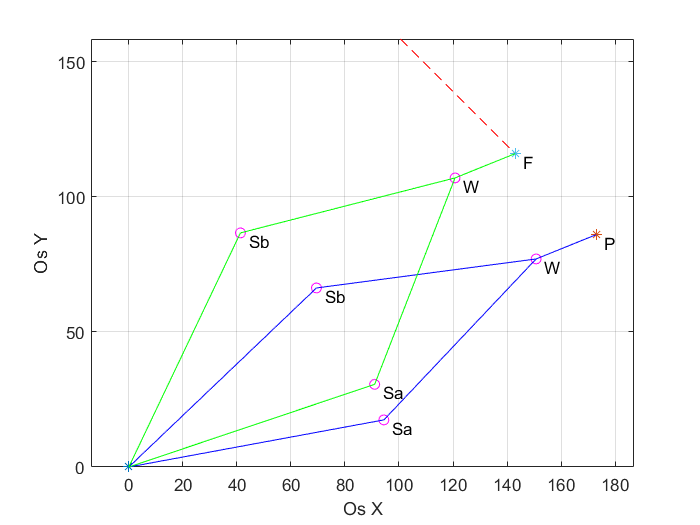

plot(pwx,pwy,'o','Color','magenta'); text(pwx+3,pwy-3,'W');

x=[pwx px];
y=[pwy py];
line(x,y,'Color','green');
plot(psxa,psya,'o','Color','magenta'); text(psxa+3,psya-3,'Sa');
x=[0 psxa];
y=[0 psya];
line(x,y,'Color','green');

plot(psxb,psyb,'o','Color','magenta'); text(psxb+3,psyb-3,'Sb');
x=[0 psxb];
y=[0 psyb];
line(x,y,'Color','green');

x=[psxa pwx];
y=[psya pwy];
line(x,y,'Color','green');

x=[psxb pwx];
y=[psyb pwy];
line(x,y,'Color','green');